load fastenerResNet18Classifier.mat

imgCorrClass = imread("fastener001023.jpg");
imgMisClass = imread("fastener001032.jpg");

imgCorrClass = imresize(imgCorrClass, [224 224]);
imgMisClass = imresize(imgMisClass, [224 224]);

[LabelCorrClass, scoresCorr] = classify(net, imgCorrClass)

LabelCorrClass = categorical
     HexNut1_4in 


scoresCorr = 1×19 single row vector
    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


[LabelMisClass, scoresMis] = classify(net, imgMisClass)

LabelMisClass = categorical
     HexNut1_4in 


scoresMis = 1×19 single row vector
    0.0000    0.0001    0.0000    0.0000    0.0000    0.6198    0.3774    0.0001    0.0020    0.0000    0.0000    0.0000    0.0004    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000


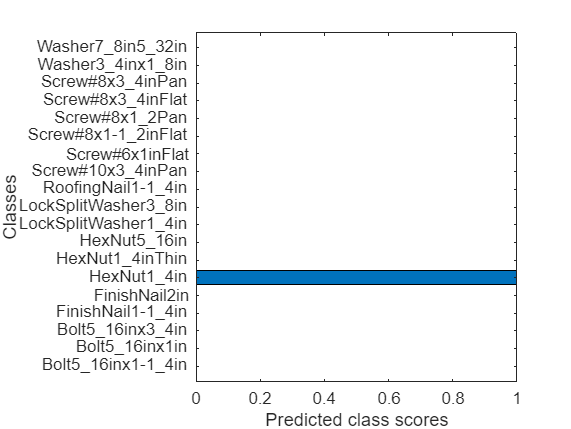

classes = net.Layers(end).Classes;
string_classes = replace(string(classes), "_", "\_");

figure
barh(classes, scoresCorr)
xlim([0 1])
xlabel("Predicted class scores")
yticklabels(string_classes)
ylabel("Classes")

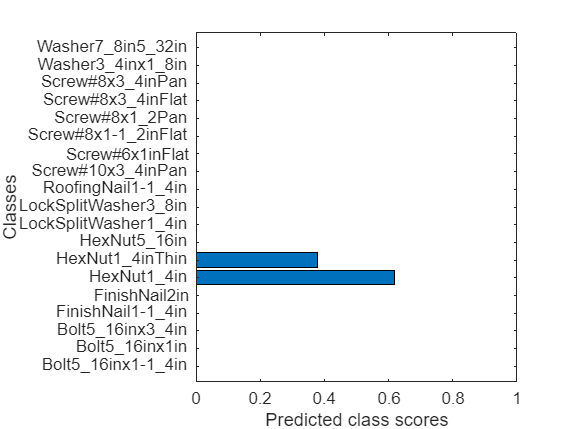


barh(classes, scoresMis)
xlim([0 1])
xlabel("Predicted class scores")
yticklabels(string_classes)
ylabel("Classes")

mapCorrClass = occlusionSensitivity(net, imgCorrClass, LabelCorrClass);
mapMisClass = occlusionSensitivity(net, imgMisClass, LabelMisClass);

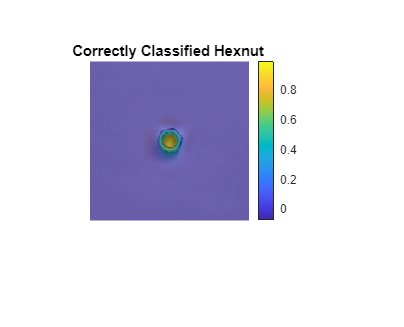

% Visualize occlusion map for the predicted class
imshow(imgCorrClass)
hold on
imagesc(mapCorrClass, "AlphaData", 0.5)
hold off
title("Correctly Classified Hexnut ")
colorbar

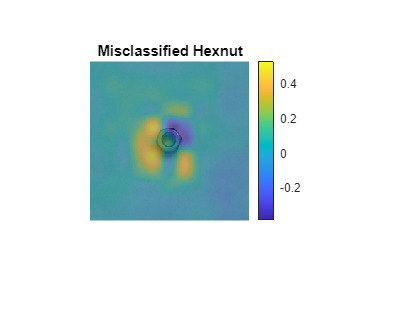


% Visualize the occlusion map for the correct class
imshow(imgMisClass)
hold on
imagesc(mapMisClass, "AlphaData",0.5)
hold off
title("Misclassified Hexnut")
colorbar